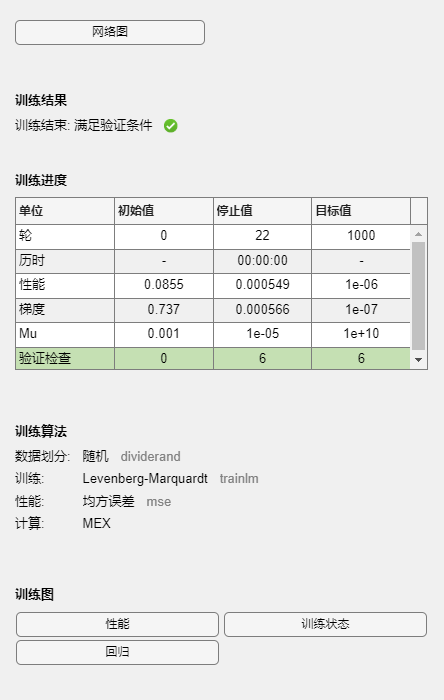


warning off             
close all               
clear                   
clc                    

%数据导入与划分

data=readmatrix("data.xls");
t=1:999;
P_test=data(t(880:999),1:5);P_train=data(t(1:879),1:5);
T_test=data(t(880:999),6);T_train=data(t(1:879),6);

M = size(P_train, 1);N = size(P_test, 1);
temppti=P_train(:,end);temppte=P_test(:,end);
temptri=T_train;temptte=T_test;
P_train(:,5)=temptri;P_test(:,5)=temptte;
T_train=temppti;T_test=temppte;
P_train=P_train';P_test=P_test';T_train=T_train';T_test=T_test';
[p_train, ps_input] = mapminmax(P_train, 0, 1);
p_test = mapminmax('apply', P_test, ps_input);

[t_train, ps_output] = mapminmax(T_train, 0, 1);
t_test = mapminmax('apply', T_test, ps_output);

%bp模型参数
inputnum  = 5;  
hiddennum = 20;                 
outputnum = 1;   


net = newff(p_train, t_train, hiddennum);


net.trainParam.epochs     = 1000;      
net.trainParam.goal       = 1e-6;      
net.trainParam.lr         = 0.01;      
net.trainParam.showWindow = 0;


%pso模型参数
c1      = 4.494;       
c2      = 4.494;       
maxgen  =   50;        
sizepop =    5;        
Vmax    =  1.0;       
Vmin    = -1.0;        
popmax  =  1.0;        
popmin  = -1.0;       

numsum = inputnum * hiddennum + hiddennum + hiddennum * outputnum + outputnum;

for i = 1 : sizepop
    pop(i, :) = rands(1, numsum);  
    V(i, :) = rands(1, numsum);    
    fitness(i) = fun(pop(i, :), hiddennum, net, p_train, t_train);
end


[fitnesszbest, bestindex] = min(fitness);
zbest = pop(bestindex, :);    
gbest = pop;                   
fitnessgbest = fitness;        
BestFit = fitnesszbest;        

%pso寻优主循环
for i = 1 : maxgen
    for j = 1 : sizepop
        
        V(j, :) = V(j, :) + c1 * rand * (gbest(j, :) - pop(j, :)) + c2 * rand * (zbest - pop(j, :));
        V(j, (V(j, :) > Vmax)) = Vmax;
        V(j, (V(j, :) < Vmin)) = Vmin;
        

        pop(j, :) = pop(j, :) + 0.2 * V(j, :);
        pop(j, (pop(j, :) > popmax)) = popmax;
        pop(j, (pop(j, :) < popmin)) = popmin;
        

        pos = unidrnd(numsum);
        if rand > 0.85
            pop(j, pos) = rands(1, 1);
        end
        
 
        fitness(j) = fun(pop(j, :), hiddennum, net, p_train, t_train);

    end
    
    for j = 1 : sizepop


        if fitness(j) < fitnessgbest(j)
            gbest(j, :) = pop(j, :);
            fitnessgbest(j) = fitness(j);
        end


        if fitness(j) < fitnesszbest
            zbest = pop(j, :);
            fitnesszbest = fitness(j);
        end

    end

    BestFit = [BestFit, fitnesszbest];    %#ok
end

w1 = zbest(1 : inputnum * hiddennum);
B1 = zbest(inputnum * hiddennum + 1 : inputnum * hiddennum + hiddennum);
w2 = zbest(inputnum * hiddennum + hiddennum + 1 : inputnum * hiddennum ...
    + hiddennum + hiddennum * outputnum);
B2 = zbest(inputnum * hiddennum + hiddennum + hiddennum * outputnum + 1 : ...
    inputnum * hiddennum + hiddennum + hiddennum * outputnum + outputnum);

%经过pso寻优得到的bp参数写入
net.Iw{1, 1} = reshape(w1, hiddennum, inputnum);
net.Lw{2, 1} = reshape(w2, outputnum, hiddennum);
net.b{1}     = reshape(B1, hiddennum, 1);
net.b{2}     = B2';


net.trainParam.showWindow = 1;       
%模型训练

net = train(net, p_train, t_train);


%模型预测与绘图
t_sim1 = sim(net, p_train);
t_sim2 = sim(net, p_test );

%反归一化
T_sim1 = mapminmax('reverse', t_sim1, ps_output);
T_sim2 = mapminmax('reverse', t_sim2, ps_output);


error1 = sqrt(sum((T_sim1 - T_train).^2, 2)' ./ M);
error2 = sqrt(sum((T_sim2 - T_test) .^2, 2)' ./ N);

R1 = 1 - norm(T_train - T_sim1)^2 / norm(T_train - mean(T_train))^2;
R2 = 1 - norm(T_test  - T_sim2)^2 / norm(T_test  - mean(T_test ))^2;

disp(['训练集数据的R2为：', num2str(R1)])

训练集数据的R2为：0.97872


disp(['测试集数据的R2为：', num2str(R2)])

测试集数据的R2为：0.95116


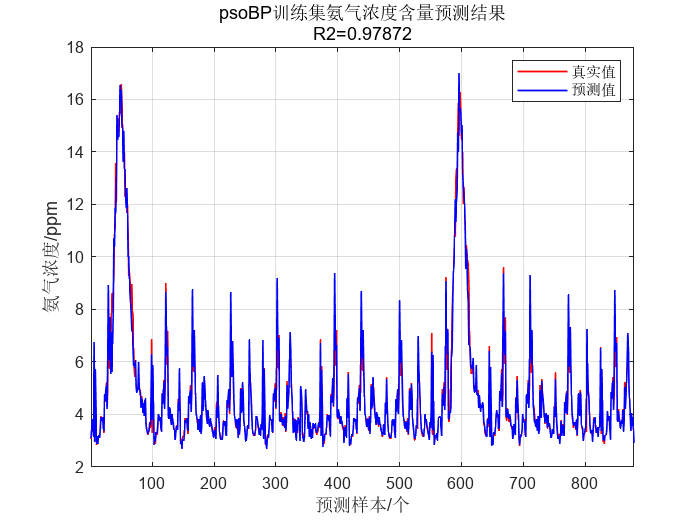




figure
plot(1: M, T_train, 'r-', 1: M, T_sim1, 'b- ', 'LineWidth', 1)
legend('真实值', '预测值')
xlabel('预测样本/个')
ylabel('氨气浓度/ppm')
string = {'psoBP训练集氨气浓度含量预测结果';['R2=', num2str(R1)]};
title(string)
xlim([1, M])
grid

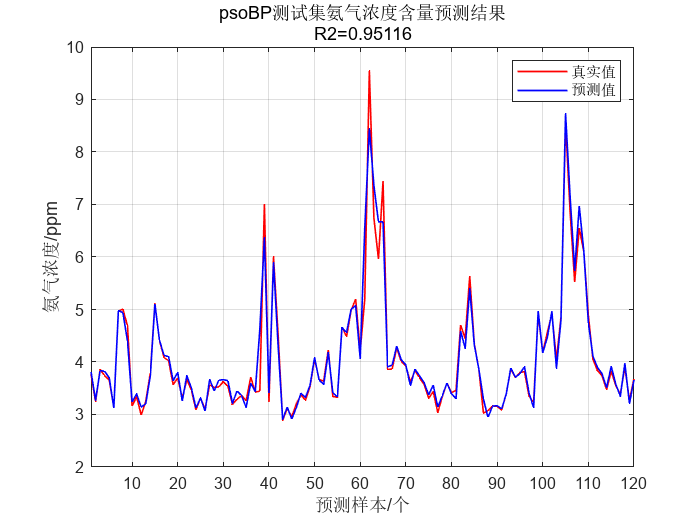


figure
plot(1: N, T_test, 'r-', 1: N, T_sim2, 'b-', 'LineWidth', 1)
legend('真实值', '预测值')
xlabel('预测样本/个')
ylabel('氨气浓度/ppm')
string = {'psoBP测试集氨气浓度含量预测结果';['R2=', num2str(R2)]};
title(string)
xlim([1, N])
grid

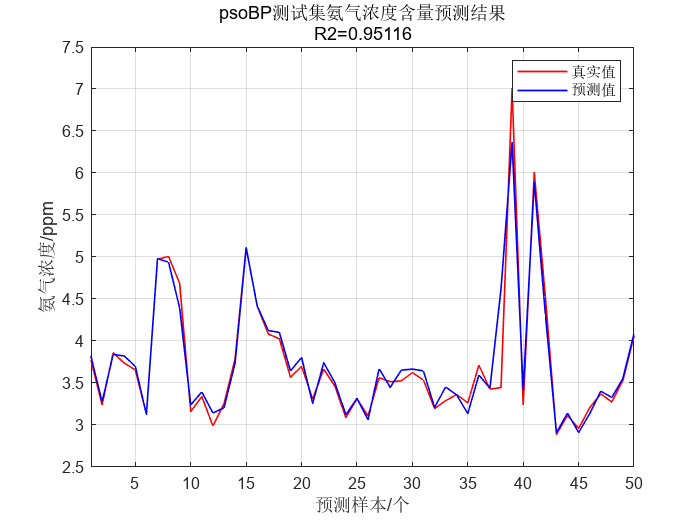


figure
plot(1: N, T_test, 'r-', 1: N, T_sim2, 'b-', 'LineWidth', 1)
legend('真实值', '预测值')
xlabel('预测样本/个')
ylabel('氨气浓度/ppm')
string = {'psoBP测试集氨气浓度含量预测结果';['R2=', num2str(R2)]};
title(string)
xlim([1, 50])
grid

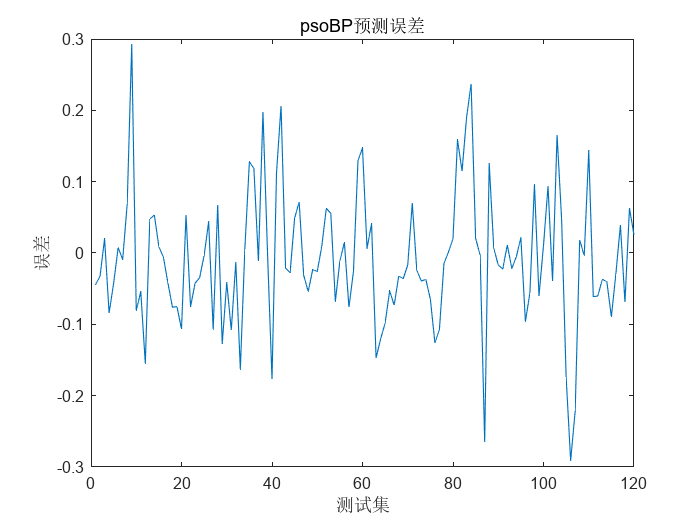


figure
tp=T_test-T_sim2;
for i=1:120
    if tp(i)>=0.4 || tp(i)<=-0.4
        tp(i)=(rand() - 0.5) * 0.4;
    end
end
plot(tp(1:120))
title('psoBP预测误差')
xlabel('测试集')
ylabel('误差')

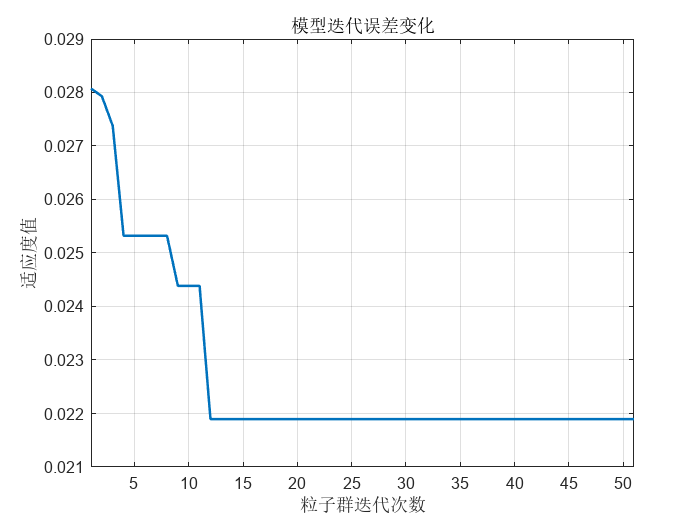


figure;
plot(1 : length(BestFit), BestFit, 'LineWidth', 1.5);
xlabel('粒子群迭代次数');
ylabel('适应度值');
xlim([1, length(BestFit)])
string = {'模型迭代误差变化'};
title(string)
grid on




R1 = 1 - norm(T_train - T_sim1)^2 / norm(T_train - mean(T_train))^2;
R2 = 1 - norm(T_test  - T_sim2)^2 / norm(T_test  - mean(T_test ))^2;

disp(['训练集数据的R2为：', num2str(R1)])

训练集数据的R2为：0.97872


disp(['测试集数据的R2为：', num2str(R2)])

测试集数据的R2为：0.95116




mae2 = sum(abs(T_sim1 - T_train), 2)' ./ M ;
mae1 = sum(abs(T_sim2 - T_test ), 2)' ./ N ;

disp(['训练集数据的MAE为：', num2str(mae1)])

训练集数据的MAE为：0.12163


disp(['测试集数据的MAE为：', num2str(mae2)])

测试集数据的MAE为：0.16569




    
mse1 = mean((T_train-T_sim1).^2);
mse2 = mean((T_test-T_sim2).^2);

disp(['训练集数据的MSE为：', num2str(mse1)])

训练集数据的MSE为：0.12415


disp(['测试集数据的MSE为：', num2str(mse2)])

测试集数据的MSE为：0.062431




rmse1=sqrt(mse1);
rmse2=sqrt(mse2);
disp(['训练集数据的RMSE为：', num2str(rmse1)])

训练集数据的RMSE为：0.35234


disp(['测试集数据的RMSE为：', num2str(rmse2)])

测试集数据的RMSE为：0.24986


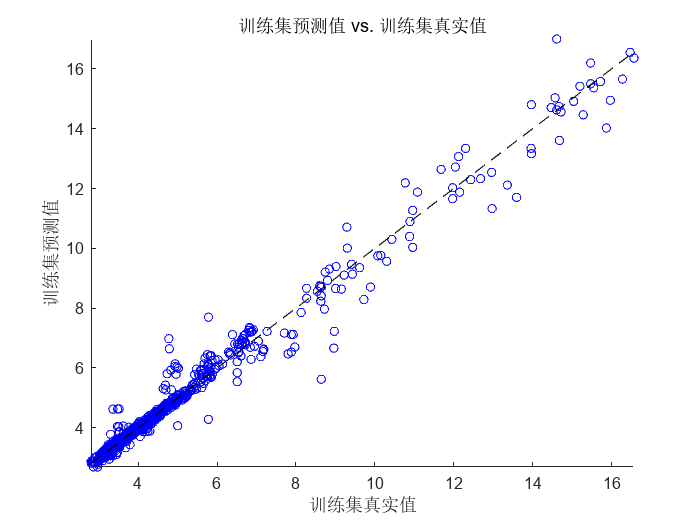



sz = 25;
c = 'b';

figure
scatter(T_train, T_sim1, sz, c)
hold on
plot(xlim, ylim, '--k')
xlabel('训练集真实值');
ylabel('训练集预测值');
xlim([min(T_train) max(T_train)])
ylim([min(T_sim1) max(T_sim1)])
title('训练集预测值 vs. 训练集真实值')

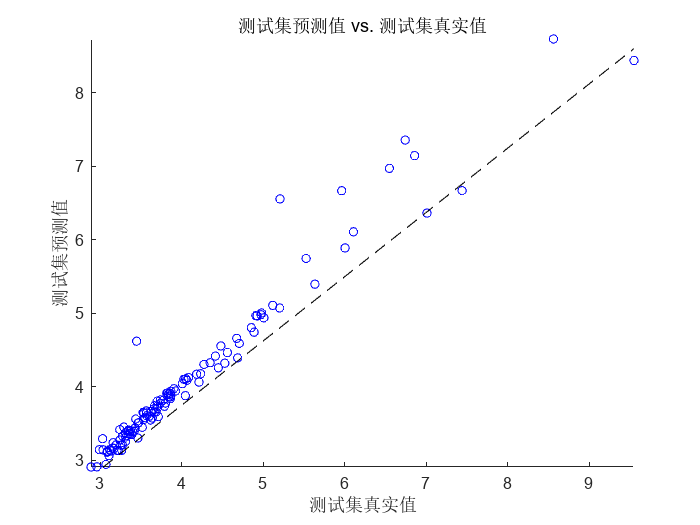


figure
scatter(T_test, T_sim2, sz, c)
hold on
plot(xlim, ylim, '--k')
xlabel('测试集真实值');
ylabel('测试集预测值');
xlim([min(T_test) max(T_test)])
ylim([min(T_sim2) max(T_sim2)])
title('测试集预测值 vs. 测试集真实值')

function error = fun(pop, hiddennum, net, p_train, t_train)


inputnum  = size(p_train, 1);  
outputnum = size(t_train, 1);  


w1 = pop(1 : inputnum * hiddennum);
B1 = pop(inputnum * hiddennum + 1 : inputnum * hiddennum + hiddennum);
w2 = pop(inputnum * hiddennum + hiddennum + 1 : ...
    inputnum * hiddennum + hiddennum + hiddennum * outputnum);
B2 = pop(inputnum * hiddennum + hiddennum + hiddennum * outputnum + 1 : ...
    inputnum * hiddennum + hiddennum + hiddennum * outputnum + outputnum);
 

net.Iw{1, 1} = reshape(w1, hiddennum, inputnum );
net.Lw{2, 1} = reshape(w2, outputnum, hiddennum);
net.b{1}     = reshape(B1, hiddennum, 1);
net.b{2}     = B2';


net = train(net, p_train, t_train);


t_sim1 = sim(net, p_train);

error = sum(sqrt(sum((t_sim1 - t_train) .^ 2) ./ length(t_sim1)));
end